# Numerical methods - Lab 3

Name: Zhu Chenhao

HDU ID: 22320630

hwc = hwc_connect('https://dss2025.hdu.vedyakov.com');
task = hwc.get_task(3);

N = task.parameters.N;
T1 = task.parameters.T1;
T2 = task.parameters.T2;
a = task.parameters.a;
b = task.parameters.b;
c = task.parameters.c;
check_point_1 = task.parameters.check_point_1;
check_point_2 = task.parameters.check_point_2;
d = task.parameters.d;
init1 = task.parameters.init1;
init2 = task.parameters.init2;
m = task.parameters.m;
ode_num1 = task.parameters.ode_num1;
ode_num2 = task.parameters.ode_num2;
phi = task.parameters.phi;
r = task.parameters.r;
step1 = task.parameters.step1;
step2 = task.parameters.step2;
w = task.parameters.w;

## Part 1: Function of Exponents

% Part 1: Function of Exponents
f = @(t, phi) derivative_phi(t, a, b, N);

[t_num, phi_num] = ode2(f, [0, T1], init1, step1);

phi_analytical = @(t) init1 + sum(a ./ b .* (1 - exp(-b * t)), 1);

phi_anal = phi_analytical(t_num);
phi_error = phi_anal(:) - phi_num(:);
error_value = phi_error(check_point_1 + 1);

% Part 2: Nonlinear System
u_func = @(t) interp1(t_num, phi_num, t, 'linear', 'extrap');

f_system = @(t, x) nonlinear_system(t, x, m, r, c, d, u_func);
[t_sys, x_sys] = ode2(f_system, [0, T2], init2, step2);

y = x_sys(:, 1);
function_value_2 = y(check_point_2 + 1);

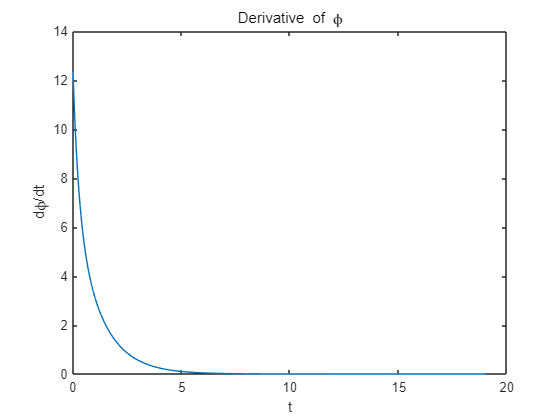


figure;
t_plot = 0:0.01:T1;
dphi_plot = arrayfun(@(t) derivative_phi(t, a, b, N), t_plot);
plot(t_plot, dphi_plot);
title('Derivative of \phi');
xlabel('t');
ylabel('d\phi/dt');

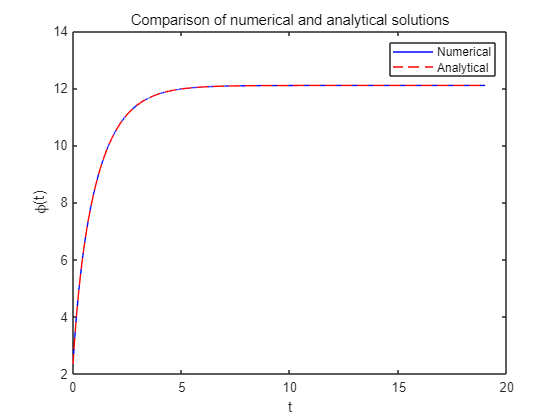


% 8
figure;
plot(t_num, phi_num, 'b-', t_num, phi_anal, 'r--');
legend('Numerical', 'Analytical');
title('Comparison of numerical and analytical solutions');
xlabel('t');
ylabel('\phi(t)');

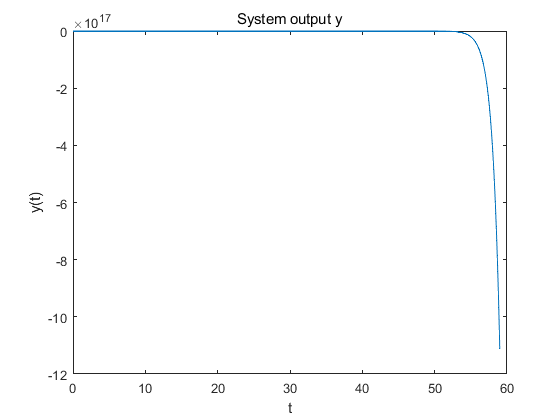




% 8d
figure;
plot(t_sys, y);
title('System output y');
xlabel('t');
ylabel('y(t)');

## Answers

task.answers.error_value = error_value;
task.answers.function_value_1 = function_value_1;
task.answers.function_value_2 = function_value_2;
task.answers

ans = 包含以下字段的 struct :
         error_value: -3.7715e-10
    function_value_1: 12.0949
    function_value_2: -50.2497


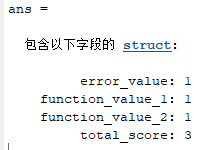

function dphi = derivative_phi(t, a, b, N)
    dphi = 0;
    for k = 1:N
        dphi = dphi + a(k) * exp(-b(k) * t);
    end
end
function [t, y] = ode2(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    num_steps = length(t);
    
    y = zeros(num_steps, length(y0));
    y(1,:) = y0';
    
    for i = 1:num_steps-1
        current_t = t(i);
        current_y = y(i,:)';
        
        k1 = f(current_t, current_y);
        
        k2 = f(current_t + (2/3)*h, current_y + (2/3)*h*k1);
        
        y(i+1,:) = current_y' + h*((1/4)*k1 + (3/4)*k2)';
    end
end
function dx = nonlinear_system(t, x, m, r, c, d, u)
    x1 = x(1); x2 = x(2);
    u_t = u(t);
    dx1 = x2;
    dx2 = (-d*abs(u_t) - r*x2 - c*x1) / (m*(sin(x1) + 2));
    dx = [dx1; dx2];
end

function [time, x] = ode1(odefun, tspan, x0, T)
    
    n = size(x0, 2);    % Number of the state variables
    time = tspan(1):T:tspan(2);
    x = zeros(length(time), n);
    x(1, :) = x0;

    for i = 2:length(time) 
        dx = odefun(time(i-1), x(i-1));
        x(i) = x(i-1) + dx * T;
    end

end


function [time, x] = ode3(odefun, tspan, x0, T)
    
    n = size(x0, 2);    % Number of the state variables
    time = tspan(1):T:tspan(2);
    x = zeros(length(time), n);
    x(1, :) = x0;

    for i = 2:length(time) 
        K1 = odefun(time(i-1), x(i-1));
        K2 = odefun(time(i-1) + 1/3 * T, x(i-1) + 1/3 * T * K1);
        K3 = odefun(time(i-1) + 2/3 * T, x(i-1) + 2/3 * T * K2);
        x(i) = x(i-1) + T*(1/4 *K1 + 0*K2 + 3/4*K3);
    end

end

function [time, x] = ode4(odefun, tspan, x0, T)
    
    n = size(x0, 2);    % Number of the state variables
    time = tspan(1):T:tspan(2);
    x = zeros(length(time), n);
    x(1, :) = x0;

    for i = 2:length(time)
        t = time(i-1);
        h = T;
        xn = x(i-1,:);
        
        K1 = odefun(t, xn);
        K2 = odefun(t + h/3, xn + h/3*K1);
        K3 = odefun(t + 2*h/3, xn - h/3*K1 + h*K2);
        K4 = odefun(t + h, xn + h*K1 - h*K2 + h*K3);
        
        x(i,:) = xn + h*(1/8*K1 + 3/8*K2 + 3/8*K3 + 1/8*K4);
    end

end
